## Seven minute *hctsa*

### 0—Adding hctsa to path

Go to directory where *hctsa* is installed and run:

startup

This should add all the paths needed for *hctsa*. You can then return to this directory.

### 1—Prepare the dataset

Let's see how we structure a time-series dataset in preparation for an *hctsa* analysis. We create an input file. For this dataset:

load('INP_Bonn_EEG.mat')

This file includes:

- `labels`, a 500 x 1 cell of strings that uniquely identify each time series,

- `timeSeriesData`, a 500 x 1 cell containing vectors of time-series data, and

- `keywords`, a 500 x 1 cell of strings (class labels)

### 2—Initialize

Now that we have our input file, we can initialize our *hctsa* data file that will contain all the results of our feature extraction and other processing we might want to do to it.

We could do this with the full *hctsa* feature set as simply `TS_Init('INP_Bonn_EEG.mat','hctsa')`, but computing the results of the full *hctsa* feature set will take some hours to complete for this dataset… :-/

So today we'll do it with a reduced feature set, the fast subset of 22 features, *catch22*, as:

tellMeEverything = false; % turn on for the full experience
TS_Init('INP_Bonn_EEG.mat','catch22',tellMeEverything)

This generates an `HCTSA.mat` file. Assuming we did the catch22 version, we can select it to see what's inside (including):

- `TS_DataMat`, a 500 (time series x 22 (features) matrix of calculated features (empty for now),

- `TimeSeries`, a 500-row table with information about time series, and

- `Operations`, a 22-row table with information about all of the features.

### 3—Extract features

We can fill in all the blanks in `TS_DataMat` with actual computed features for each combination of time series and features as:

TS_Compute(false);

### 4—Process the Results

We can next tell *hctsa* how to use information in the `keywords` part of our input file to label the classes in the dataset. In this case it's straightforward since we just have a single unique label for each class, so we can just run:

TS_LabelGroups();

If we have some extra time, we could take a peek at some examples, as:

TS_PlotTimeSeries()

And we can filer out features with many missing values, and normalize them to a common scale as:

TS_Normalize();

This saves the result in a new file, `HCTSA_N.mat`

### 5—Visualize/Play/Analyze!

We can play with a quick low-dimensional representation of the dataset in the feature space as:

TS_LowDimInspect('norm','tsne') % must be run in commandline for interactive window

And we could quickly get a sense for how accurately we can classify the time series in the 22-dimensional feature space:

Loading data from HCTSA_N.mat... Done.
Only considering the 200 time series that have labels.
2 classes assigned to the time series in this dataset:
Class 1: eyesOpen (100 time series)
Class 2: seizure (100 time series)

Training and evaluating a 2-class linear SVM classifier (low-dimensional) using 10-fold cross validation
Resetting random seed for reproducibility

Mean +/- std (across 10 folds) accuracy (2-class) using svm-linear-lowdim classification with 22 features:
99.500 +/- 1.581%
[Training folds: mean = 99.944%, std = 0.176% across 10 folds].

Looks good? Don't forget to compare results using other (simpler) methods...


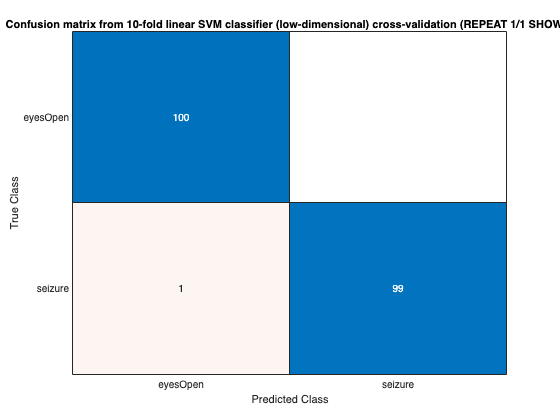

TS_Classify('norm')

Try again with an radial basis function SVM classifier:

Loading data from HCTSA_N.mat... Done.
Only considering the 200 time series that have labels.
2 classes assigned to the time series in this dataset:
Class 1: eyesOpen (100 time series)
Class 2: seizure (100 time series)

Training and evaluating a 2-class linear SVM classifier (low-dimensional) using 10-fold cross validation
Resetting random seed for reproducibility


Mean +/- std (across 10 folds) accuracy (2-class) using svm-rbf classification with 22 features:
100.000 +/- 0.000%
[Training folds: mean = 100.000%, std = 0.000% across 10 folds].

Looks good? Don't forget to compare results using other (simpler) methods...


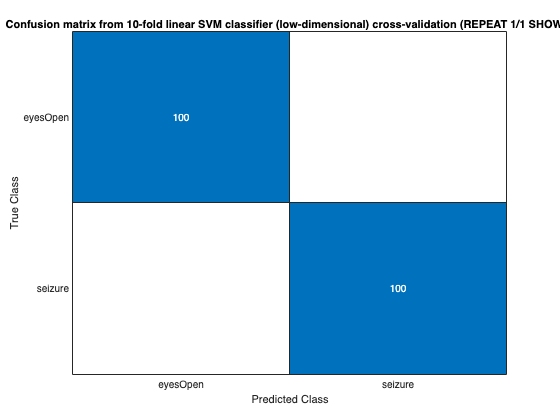

cfnParams = GiveMeDefaultClassificationParams('norm');
cfnParams.whatClassifier = 'svm-rbf';
TS_Classify('norm',cfnParams)

What are the best features?

Loading data from HCTSA_N.mat... Done.
Only considering the 200 time series that have labels.
2 classes assigned to the time series in this dataset:
Class 1: eyesOpen (100 time series)
Class 2: seizure (100 time series)
Computing the performance of 22 individual features to differentiate 2 classes using a simple linear classifier accuracy...
|::::::::::::::::::::::::::::::::::::::::|
 Done in 372ms.
Mean simple linear classifier accuracy across 22 features = 66.93%
(Random guessing for 2 equiprobable classes = 50.00%)
[5] SC_FluctAnal_2_dfa_50_1_2_logi_prop_r1 (scaling) -- 93.00%
[12] MD_hrv_classic_pnn40 (medical) -- 86.00%
[7] FC_LocalSimple_mean1_tauresrat (forecasting) -- 85.00%
[11] SB_BinaryStats_diff_longstretch0 (distribution,stationarity) -- 83.50%
[20] PD_PeriodicityWang_th0.01 (periodicity,spline) -- 80.50%
[8] SB_MotifThree_quantile_hh (symbolic,motifs) -- 76.50%
[9] CO_HistogramAMI_even_5bin_ami2 (information,correlation,AMI) -- 75.50%
[21] SC_FluctAnal_2_rsrangefit_50_1_l

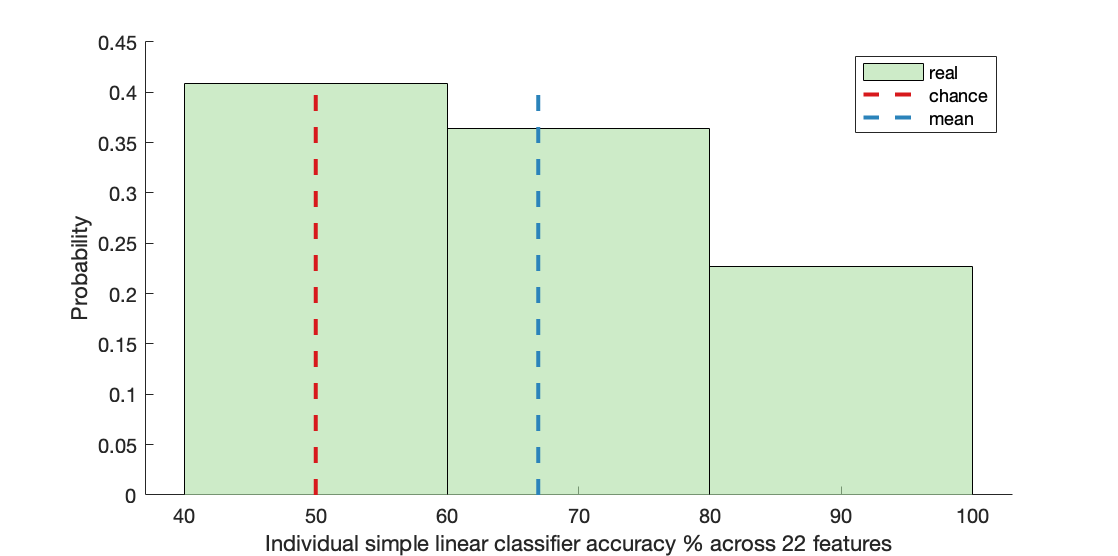

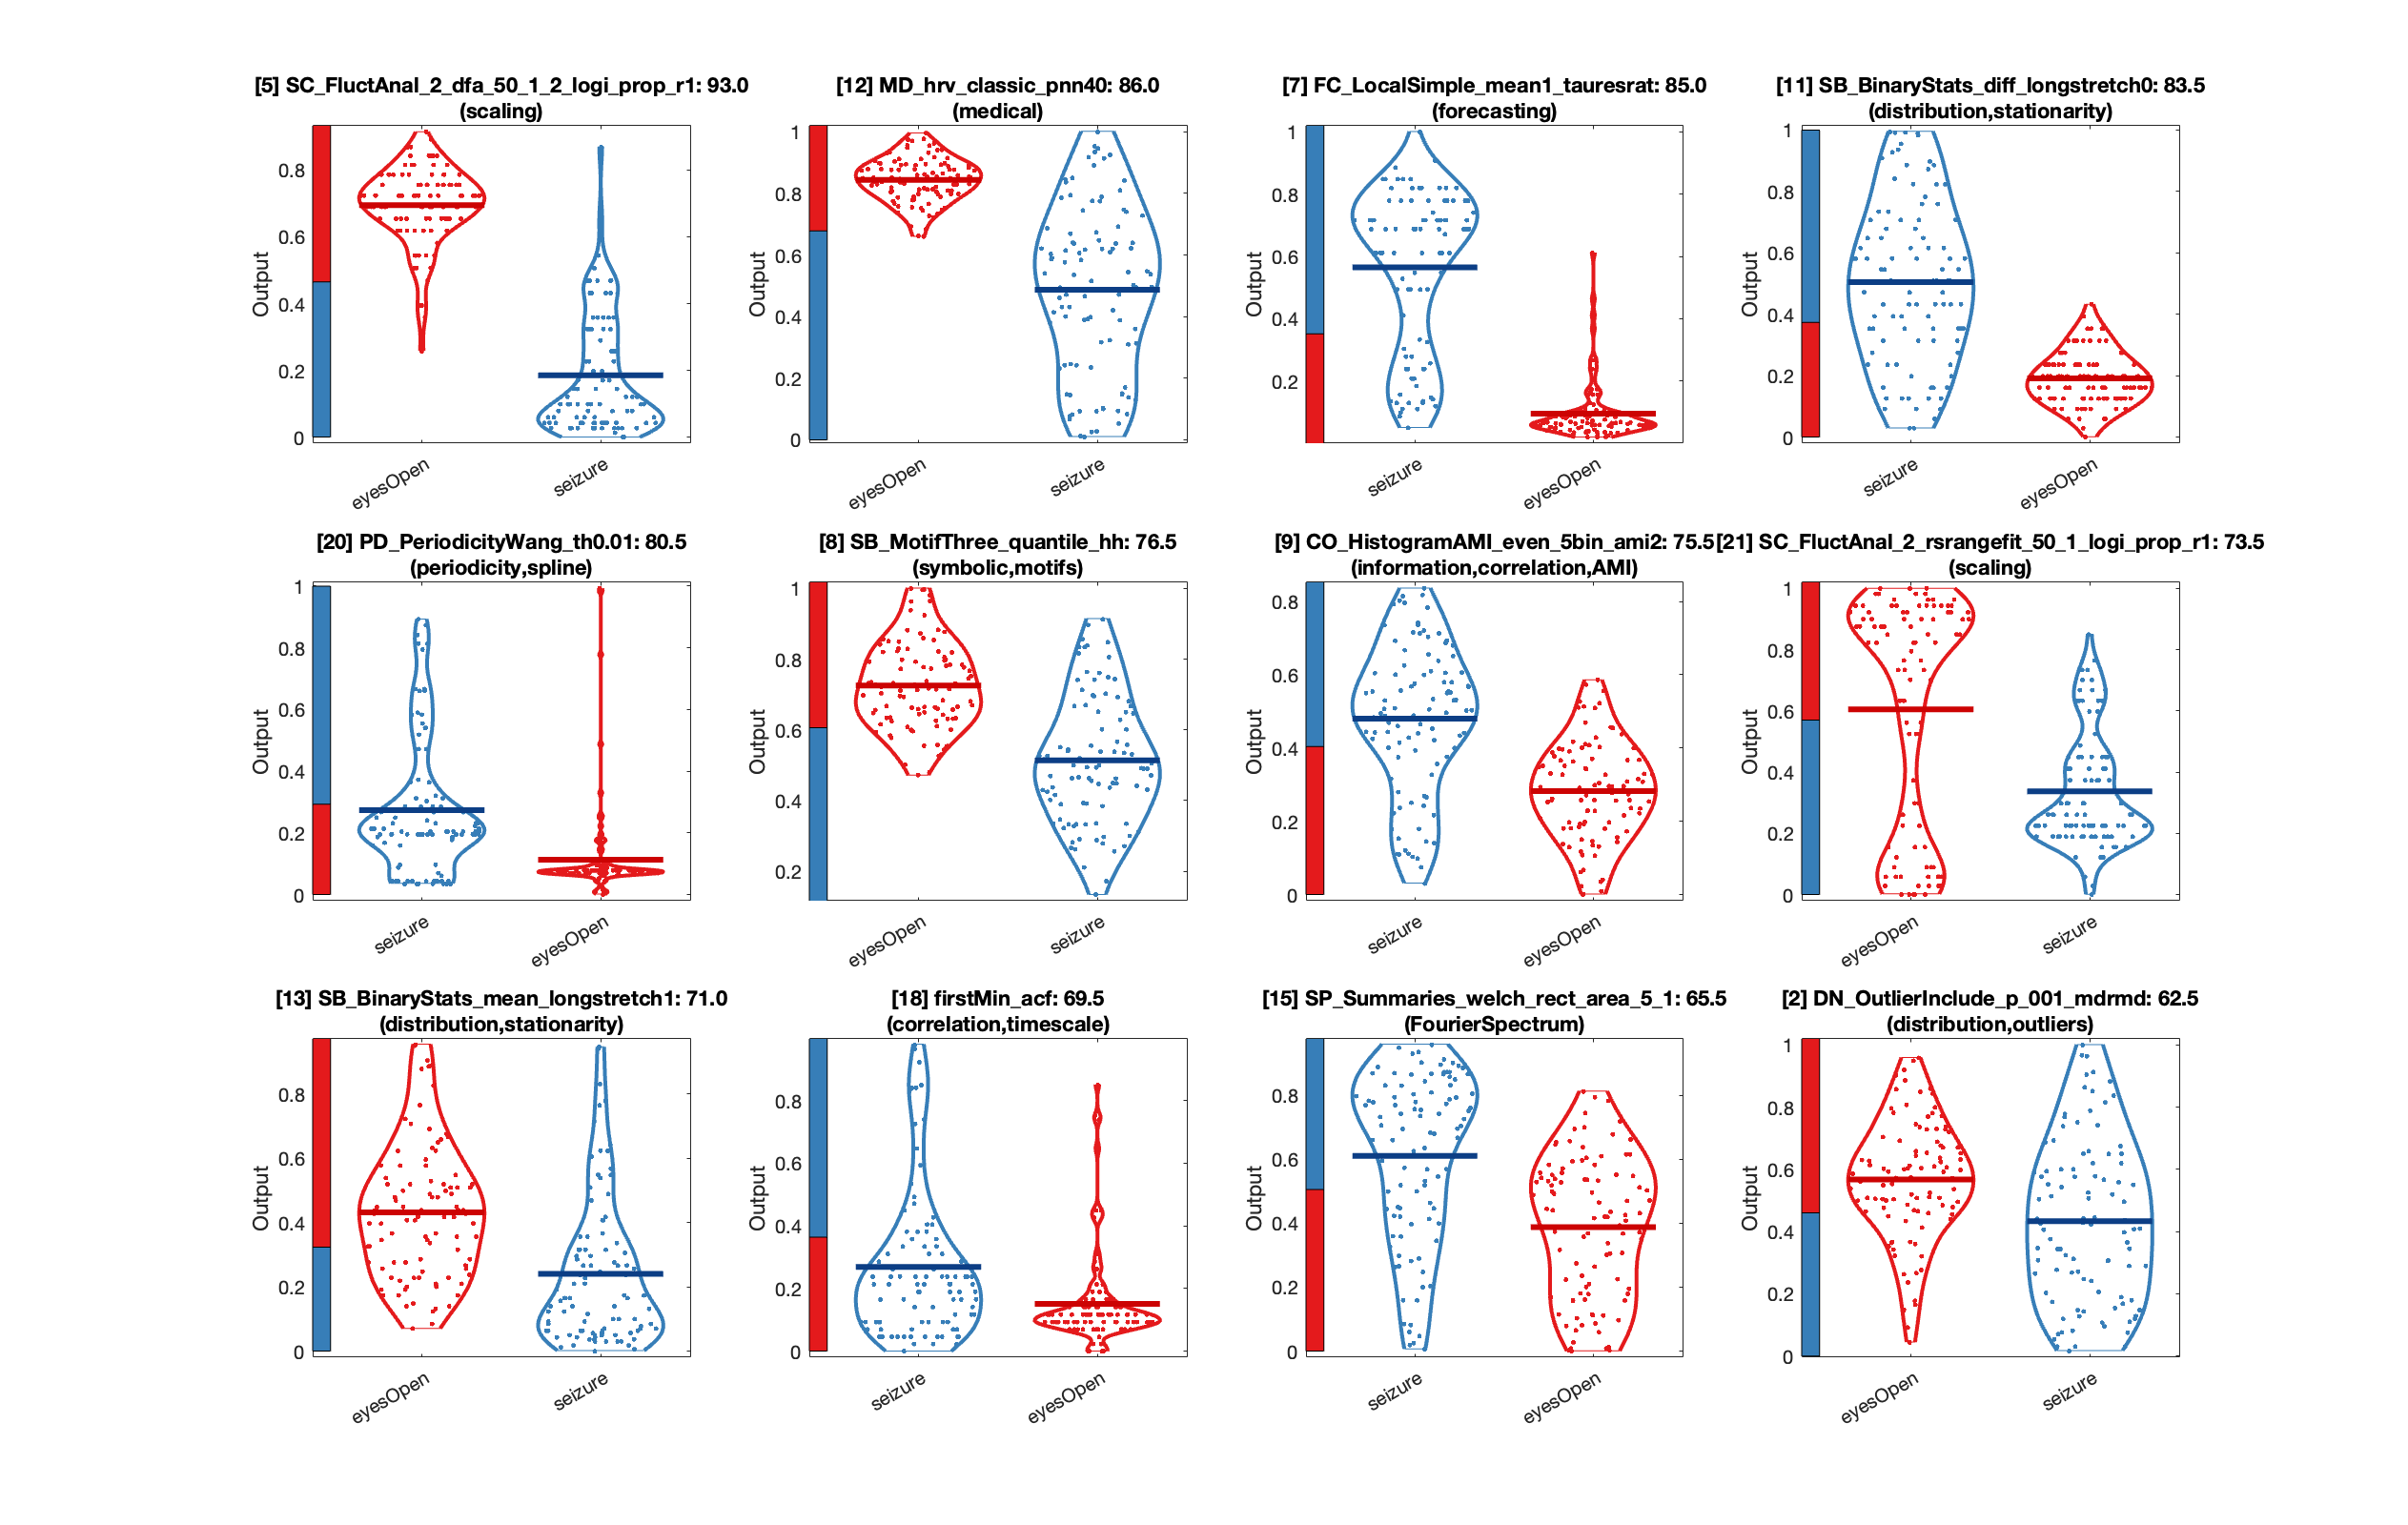

First computing pairwise distances using pdist... Done in 42ms.
Computing linkage information for 12 x 12 data using average clustering... Done.
Using optimalleaforder reordering!


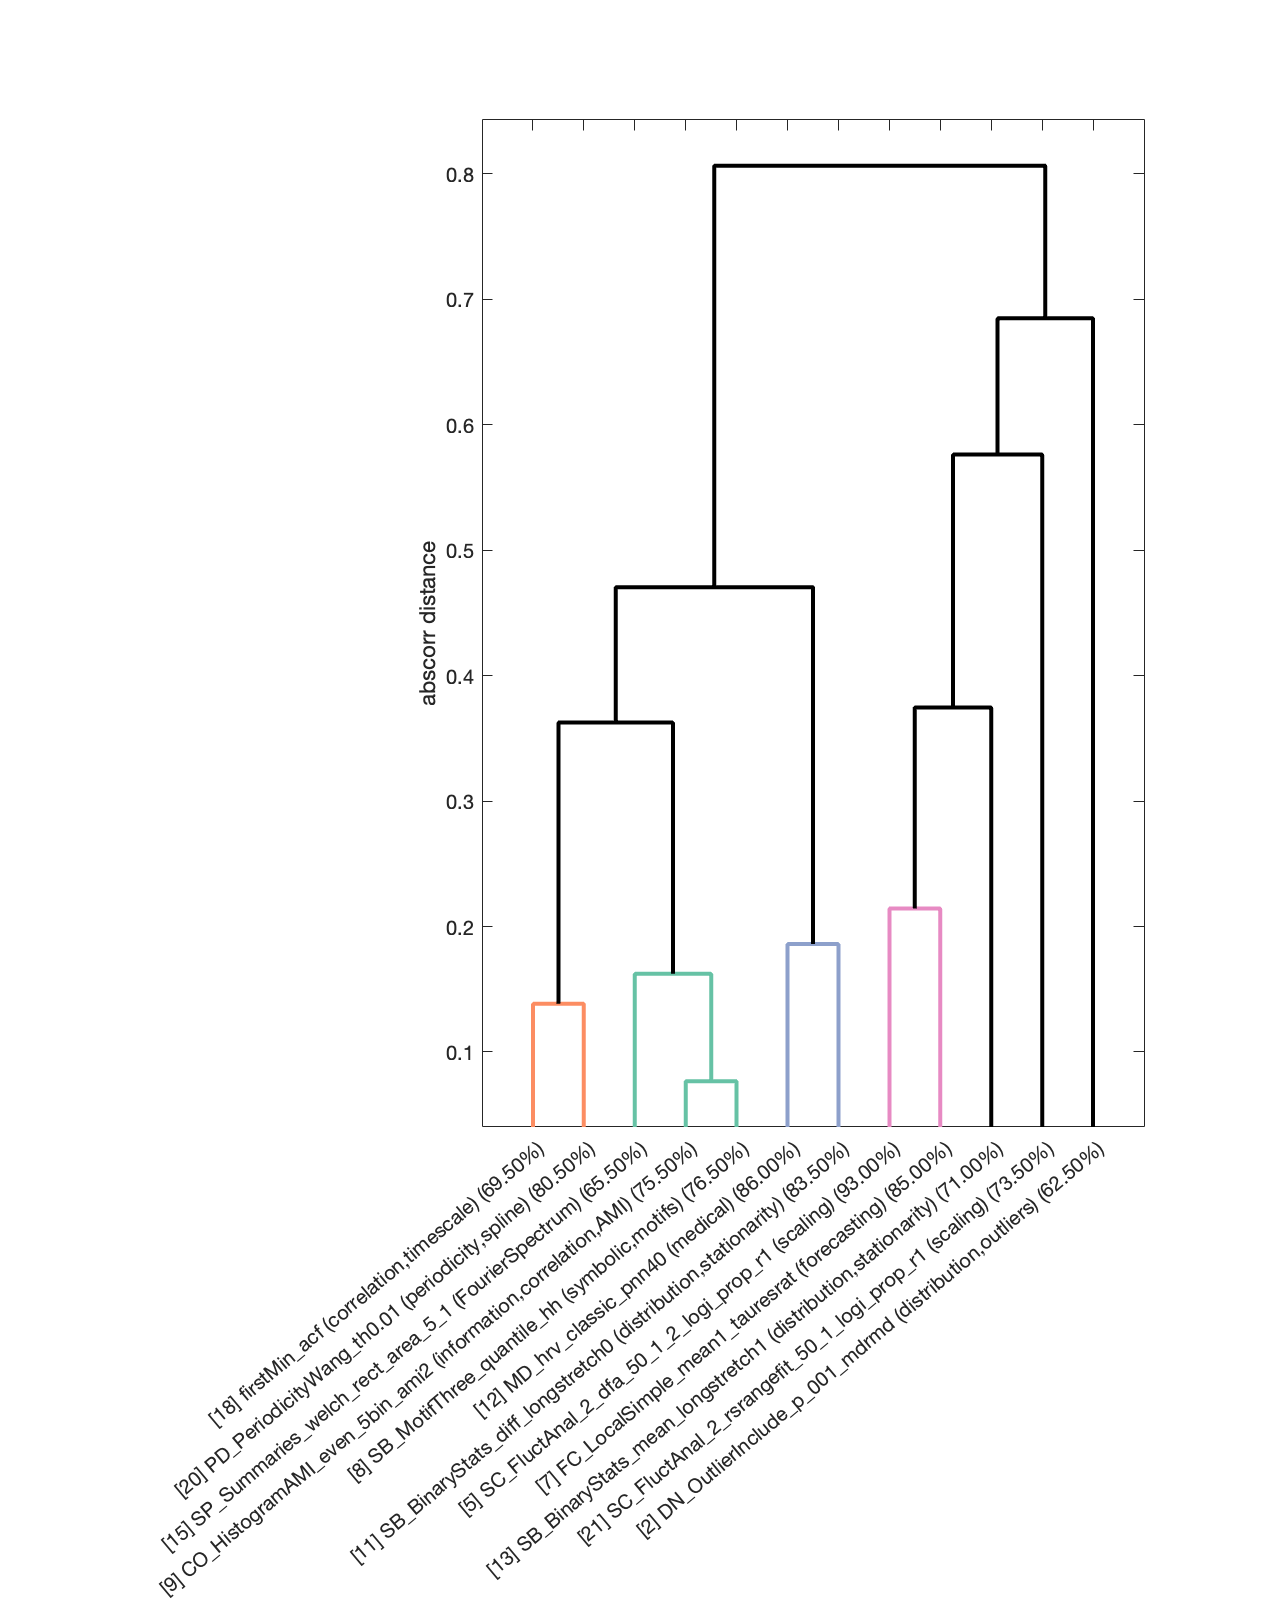

Computing linkage information for 12 x 12 data using average clustering... Done.
Using optimalleaforder reordering!
abscorr distance-based clustering with 7 clusters.


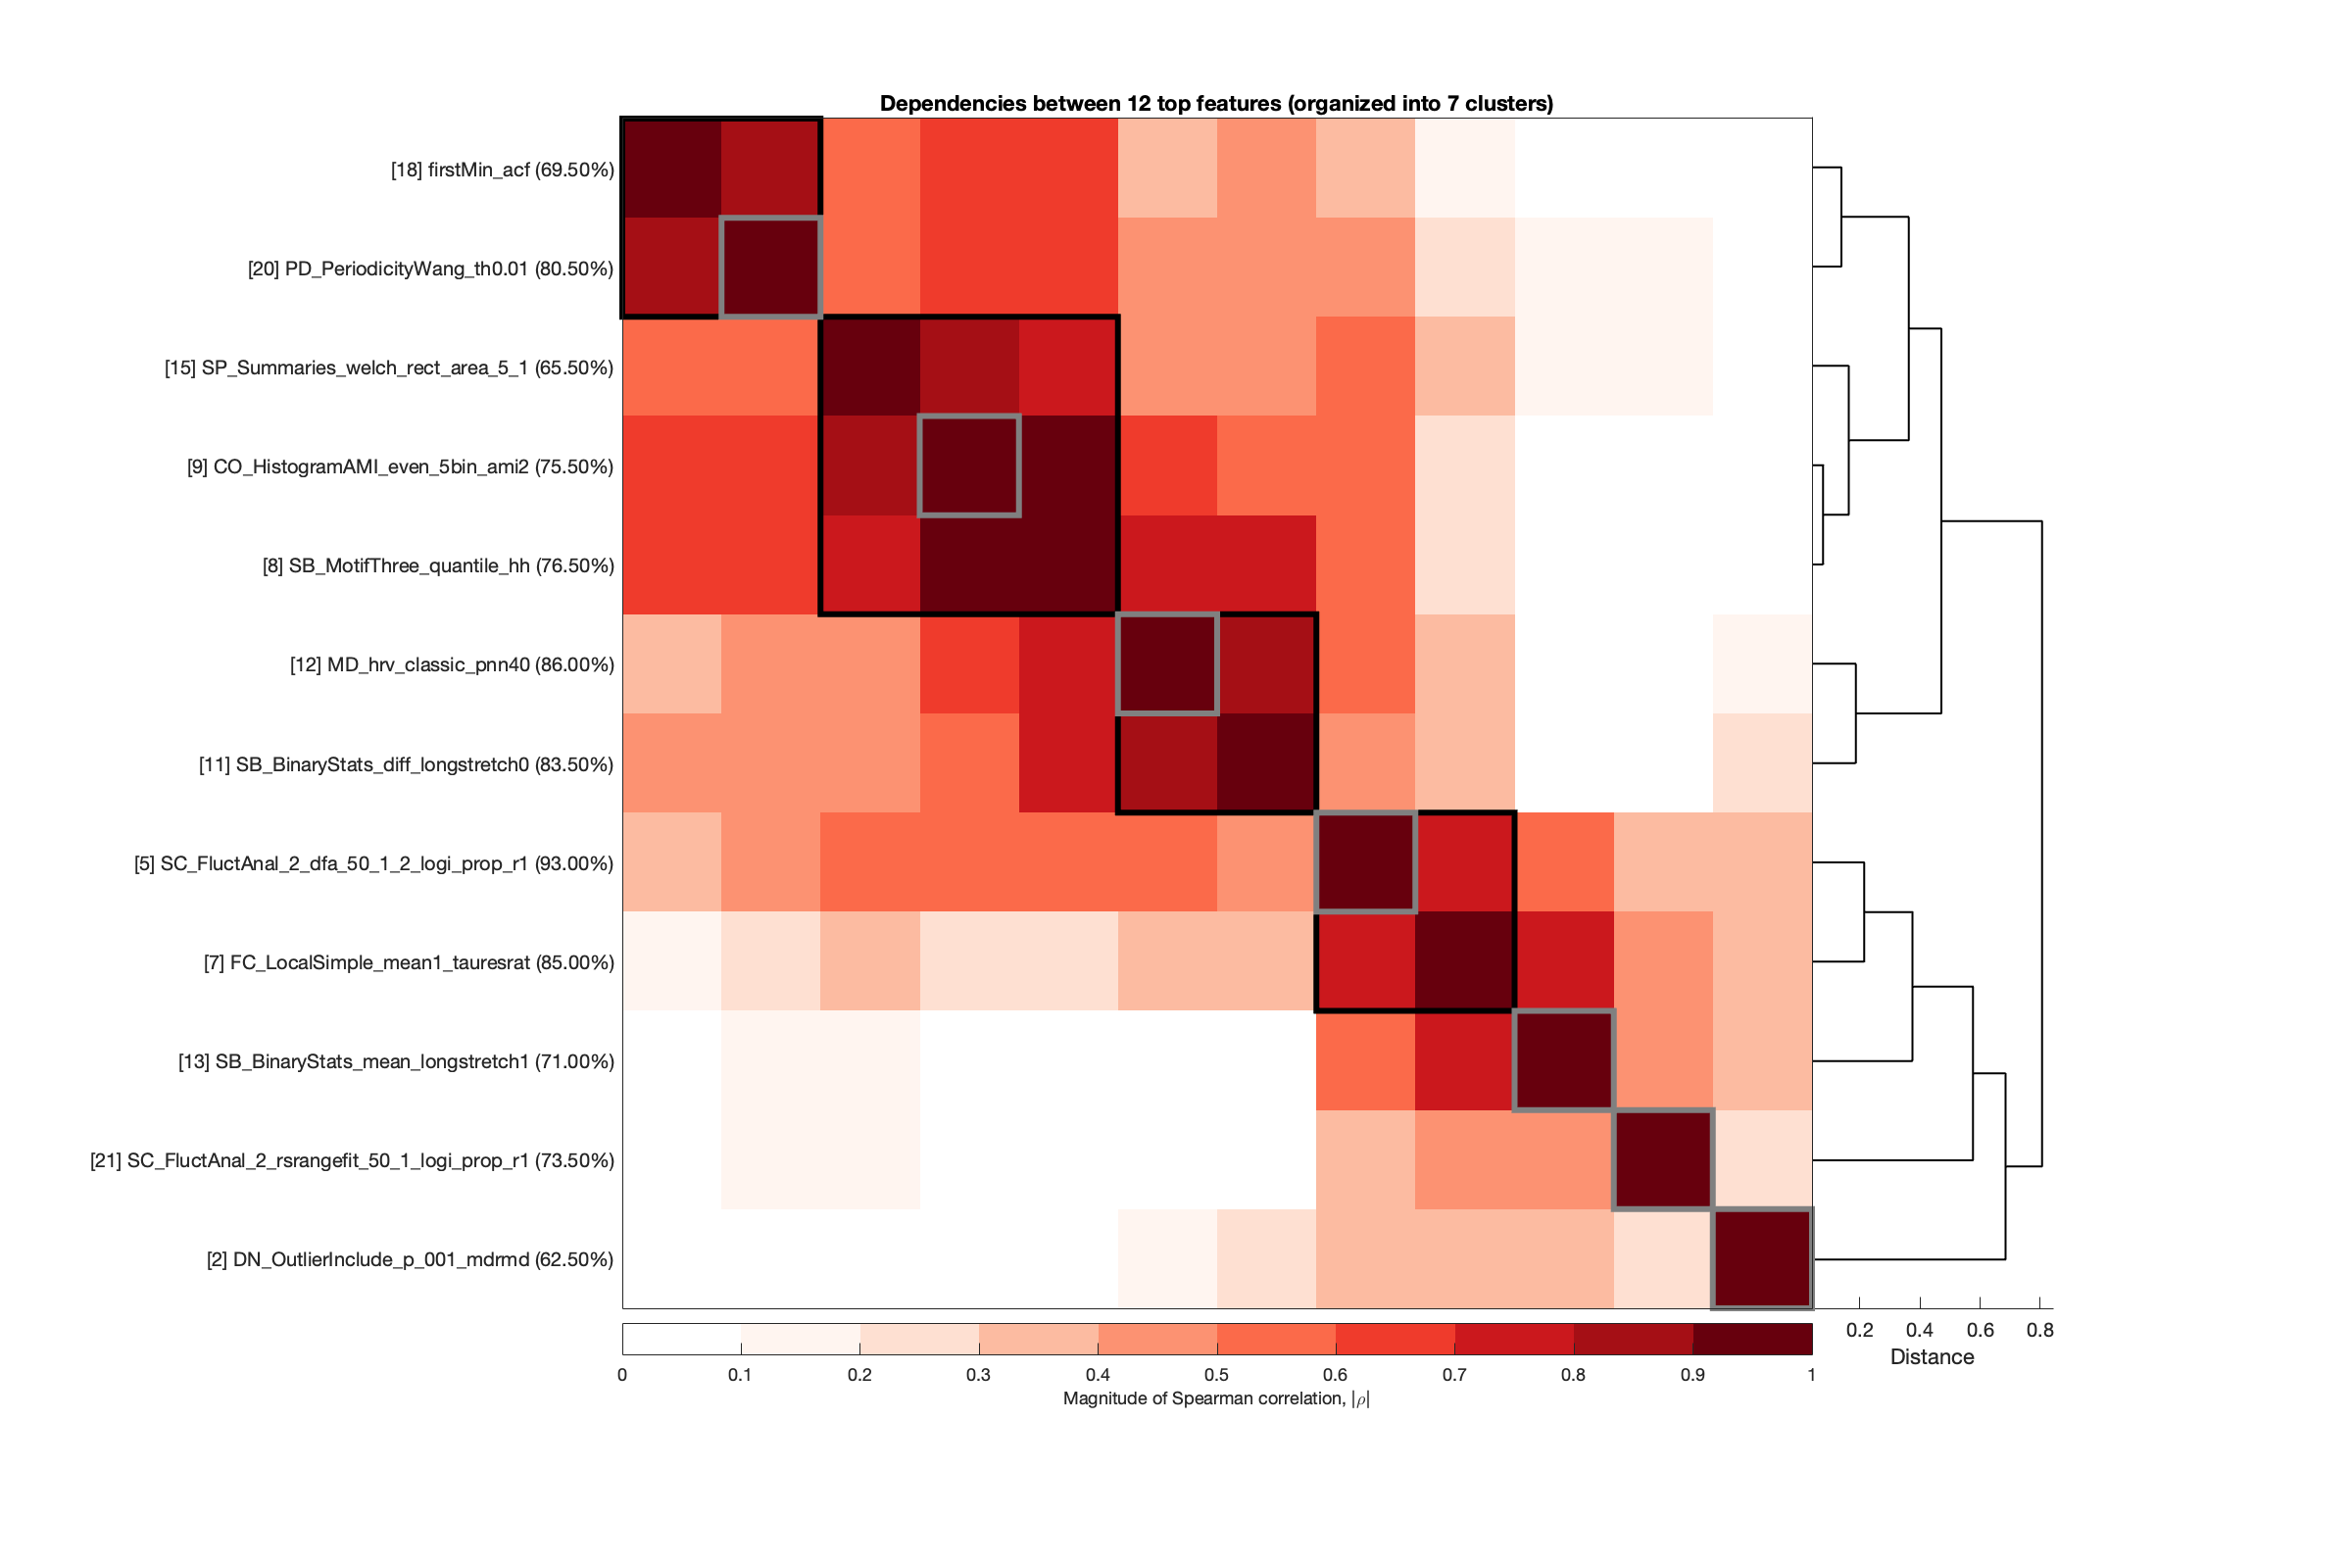

TS_TopFeatures('norm','classification',struct(),'numTopFeatures',12,'numFeaturesDistr',12)

What about for a two-class subset?

TS_LabelGroups('norm',{'eyesOpen','seizure'})

Loading data from HCTSA_N.mat... Done.
Group labeling complete in 8ms.
300/500 time series remain unlabeled (and will be ignored in any classification).
We found data for 2 labeled classes:
eyesOpen -- 100 matches (/500)
seizure -- 100 matches (/500)
Saving group labeling back to HCTSA_N.mat... Saved.


Loading data from HCTSA_N.mat... Done.
Only considering the 200 time series that have labels.
2 classes assigned to the time series in this dataset:
Class 1: eyesOpen (100 time series)
Class 2: seizure (100 time series)
Calculating 2-dimensional principal components of the 200 x 22 data matrix...
---Done.
Estimating 2-class classification rates for each feature (and in combination)...
accuracy in 2-dim space: 95.50%
Estimating classification boundaries...


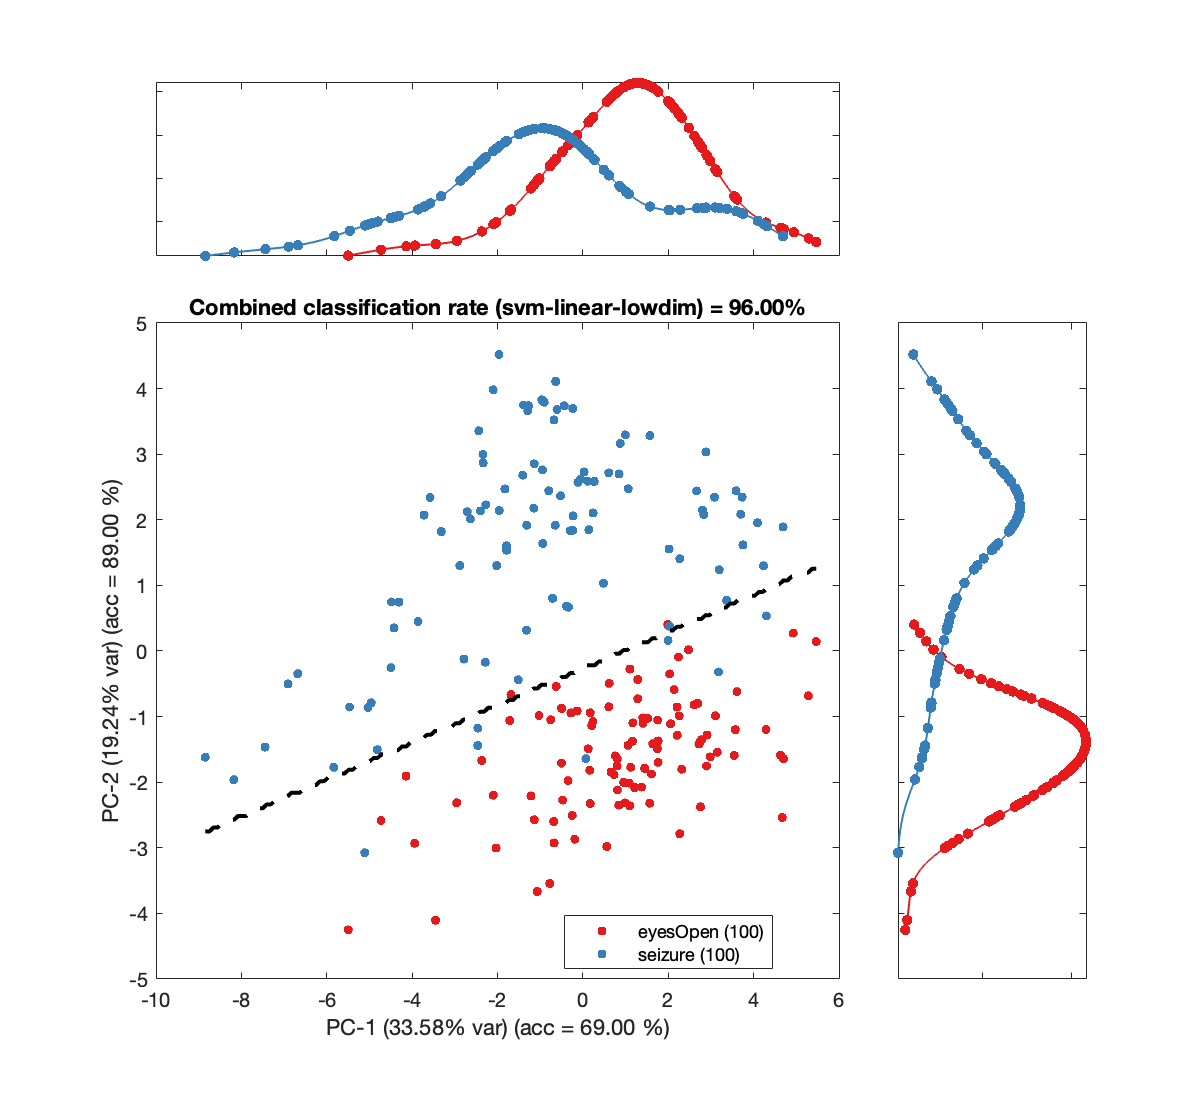

annotateParams = struct('n',0,'textAnnotation','none','userInput',false);
TS_PlotLowDim('norm','pca',true,annotateParams)

Can you classify similarly well in a lower-dimensional PCA space?

Loading data from HCTSA_N.mat... Done.
Only considering the 200 time series that have labels.
2 classes assigned to the time series in this dataset:
Class 1: eyesOpen (100 time series)
Class 2: seizure (100 time series)

Training and evaluating a 2-class linear SVM classifier (low-dimensional) using 10-fold cross validation
Computing top 10 PCs... Done.

---Top feature loadings for PC1---:
(0.338, r = 0.92) [8] SB_MotifThree_quantile_hh (symbolic,motifs)
(0.334, r = 0.91) [14] FC_LocalSimple_mean3_stderr (forecasting)
(-0.328, r = -0.89) [9] CO_HistogramAMI_even_5bin_ami2 (information,correlation,AMI)
(-0.300, r = -0.82) [18] firstMin_acf (correlation,timescale)
(0.290, r = 0.79) [16] SP_Summaries_welch_rect_centroid (FourierSpectrum)
(-0.290, r = -0.79) [20] PD_PeriodicityWang_th0.01 (periodicity,spline)
(-0.286, r = -0.78) [17] firstCrossing_1e_acf_tau (correlation,timescale)
(-0.268, r = -0.73) [15] SP_Summaries_welch_rect_area_5_1 (FourierSpectrum)
(-0.259, r = -0.71) [19] IN_AutoM

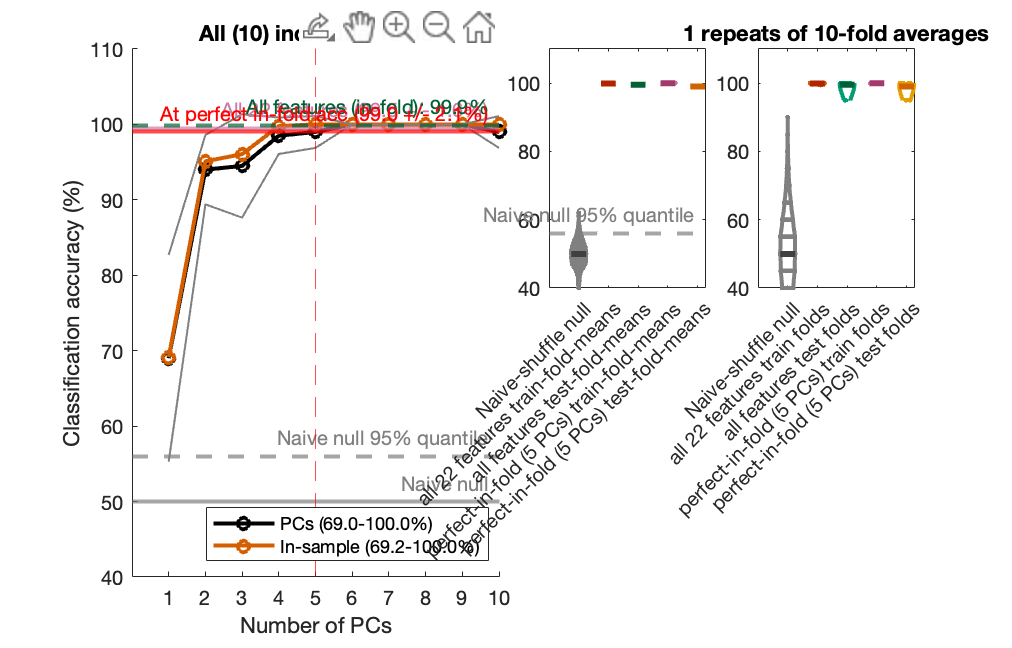

TS_ClassifyLowDim('norm')

TS_LabelGroups('norm',{'epileptogenic','hippocampus'})

Loading data from HCTSA_N.mat... Done.
Group labeling complete in 17ms.
300/500 time series remain unlabeled (and will be ignored in any classification).
We found data for 2 labeled classes:
epileptogenic -- 100 matches (/500)
hippocampus -- 100 matches (/500)
Saving group labeling back to HCTSA_N.mat... Saved.


TS_TopFeatures('norm','ttest',[],'numNulls',10)

**Probing specific features**

We want to understand individual features (run in commandline for interactive)

doInteractive = true;
myFavoriteFeatureID = 20;
TS_FeatureSummary(myFavoriteFeatureID,'raw',true,doInteractive)

Find similar matches to a given time series

Using default distance metric: Euclidean
Loading data from HCTSA_N.mat... Done.

---TARGET: [30] MD_EEG_UniBonn_Z030_LP40Hz.dat---
Computing Euclidean distances to 499 other time series... Done.
1. [64] MD_EEG_UniBonn_Z064_LP40Hz.dat (eyesOpen): d = 0.16
2. [42] MD_EEG_UniBonn_Z042_LP40Hz.dat (eyesOpen): d = 0.19
3. [29] MD_EEG_UniBonn_Z029_LP40Hz.dat (eyesOpen): d = 0.20
4. [72] MD_EEG_UniBonn_Z072_LP40Hz.dat (eyesOpen): d = 0.20
5. [178] MD_EEG_UniBonn_O078_LP40Hz.dat (eyesClosed): d = 0.20
6. [85] MD_EEG_UniBonn_Z085_LP40Hz.dat (eyesOpen): d = 0.21
7. [58] MD_EEG_UniBonn_Z058_LP40Hz.dat (eyesOpen): d = 0.22
8. [20] MD_EEG_UniBonn_Z020_LP40Hz.dat (eyesOpen): d = 0.23
9. [55] MD_EEG_UniBonn_Z055_LP40Hz.dat (eyesOpen): d = 0.23
10. [179] MD_EEG_UniBonn_O079_LP40Hz.dat (eyesClosed): d = 0.24
11. [33] MD_EEG_UniBonn_Z033_LP40Hz.dat (eyesOpen): d = 0.24
12. [45] MD_EEG_UniBonn_Z045_LP40Hz.dat (eyesOpen): d = 0.24
13. [96] MD_EEG_UniBonn_Z096_LP40Hz.dat (eyesOpen): d = 0.24
14. [48] MD_EEG

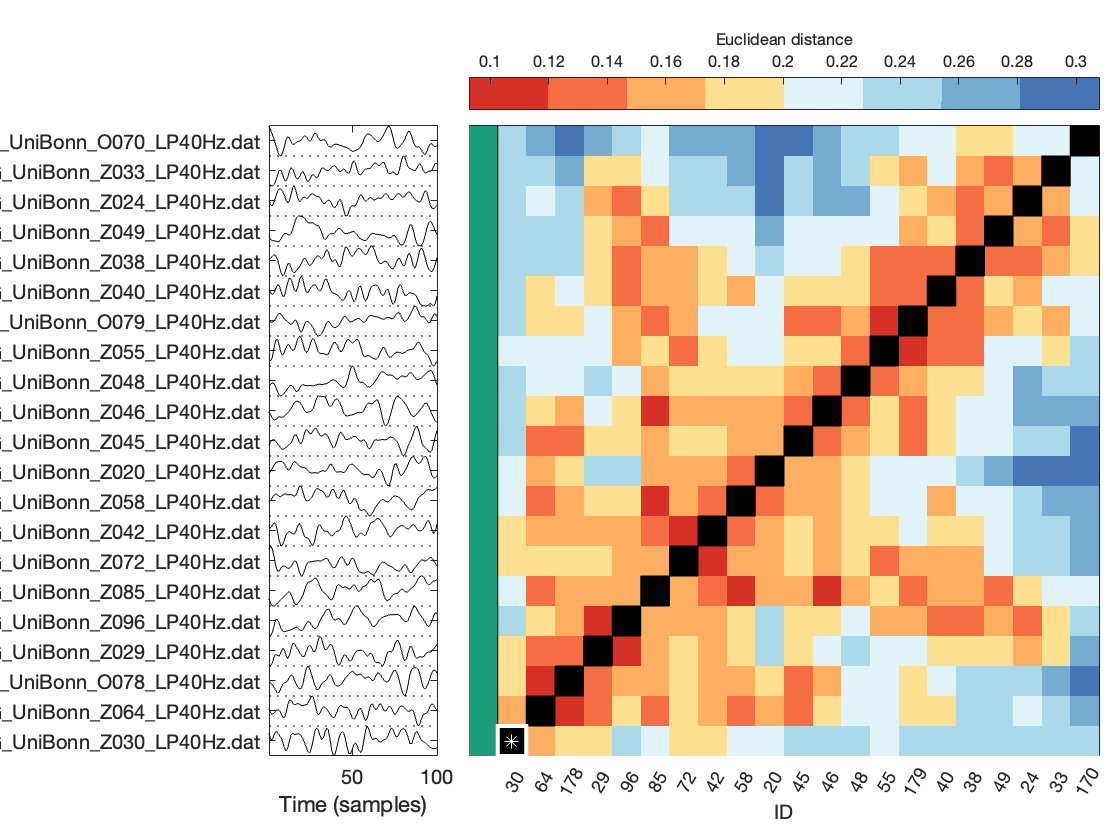

TS_LabelGroups('norm')
timeSeriesID = 30;

TS_SimSearch(timeSeriesID,'ts')